## Initial setup

% clear memory, figures, command window, output numbers in standard notation
clear all;
close all;
clc;
format long g;

## User Inputs

prn = 12;

preciseFile = 'Ephemeris Files of Jan 08th, 2022/igs21916.sp3';
brdcFile = 'Ephemeris Files of Jan 08th, 2022/brdc0080.22n';
almanacFile = 'Ephemeris Files of Jan 08th, 2022/Almanac-SatPos-PRN12.txt';
urPredFile = 'Ephemeris Files of Jan 08th, 2022/igu21916_00.sp3';
urObsFile = 'Ephemeris Files of Jan 08th, 2022/igu21920_00.sp3';

## Sky plot of satellkite

%Read the sp3 file  
precisedata_0 = readSP3(preciseFile);
precisedata = NaN(96,4);
for j = 1:96
    % Time of transmission
    time_of_transmission = 518400 + (j - 1) * 900;

    % Iterate through urPreddata_0 and filter rows
    for i = 1:size(precisedata_0, 1)
        % Check if the first number is 12 and third number equals time_of_transmission
        if precisedata_0(i, 1) == 12 && precisedata_0(i, 3) == time_of_transmission
            % Store columns 3, 4, 5, and 6 in urPreddata
            precisedata(j, :) = [precisedata_0(i, 3), precisedata_0(i, 4), precisedata_0(i, 5), precisedata_0(i, 6)];
        end
    end
end
%calculate the vector from receiver to satellites in xyz
%transform the vector to ENU
%calculate the azimuth and elevation
%plot the sky plot
%calculate the DOP

## Task2 - Satellite Position Computations

% Read .22n
fileID = fopen(brdcFile, 'r');

% to store every line
brdcdata = {};

% read data until 9th
for i = 1:8
    line = fgetl(fileID);
end

% extract data from 9th
lineNum = 1;
while ~feof(fileID)
    line = fgetl(fileID);
    line = strrep(line, 'D', 'E');
    tokens = str2double(regexp(line, '([-+]?\d+\.\d+E[+-]\d+|[-+]?\d+(\.\d+)?)', 'match'));

    dataMatrix = tokens;
    brdcdata{lineNum} = dataMatrix;

    lineNum = lineNum + 1;
end

% close file
fclose(fileID);

% to store the consolidated data
brdcData = {};

% loop through the brdcdata array
index = 1;
while index <= numel(brdcdata)
    % Find the 1x10 cell (this is the start of a new block)
    if numel(brdcdata{index}) == 10
        % Create a temporary array to store the current block's data
        currentBlock = NaN(8, 10);  % Initialize 8 rows, 10 columns
        
        % Fill the first row with the 1x10 data
        currentBlock(1, :) = brdcdata{index};  % First row is 1x10 cell

        % Loop through the next 7 rows of data (each with 1x4 cells)
        for i = 1:7
            index = index + 1;  % Move to the next row
            if index <= numel(brdcdata)
                % Fill the current row (1x4 data) into the currentBlock matrix
                currentBlock(i + 1, 1) = brdcdata{index}(1);  % First element of 1x4 data
                currentBlock(i + 1, 2) = brdcdata{index}(2);  % Second element of 1x4 data
                currentBlock(i + 1, 3) = brdcdata{index}(3);  % Third element of 1x4 data
                currentBlock(i + 1, 4) = brdcdata{index}(4);  % Fourth element of 1x4 data
            end
        end
        
        % Add the reorganized data block as a new row in newBrdcData
        brdcData{end+1} = currentBlock;
    end
    index = index + 1;  % Move to the next 1x10 cell
end

% Extract PRN 12 Data
prn12_data = {};  % Empty cell array to store PRN 12 data

for i = 1:length(brdcData)
    % Convert first element of each block (PRN) to a number
    PRN = brdcData{i}(1, 1);
    
    % If PRN matches 12, store it
    if PRN == 12
        prn12_data{end+1} = brdcData{i};
    end
end

% Using the best and the first broadcast ephemeris record to do the
% computation
brdcbest = NaN(96,4);
brdc24hr = NaN(96,4);

for j = 1:96
    % Time of transmission
    time_of_transmission = 518400 + (j-1) * 900;
    timediff = zeros(1,13);
    
    % Find the nearest Toe for best ephemeris
    for i = 1:13
        Toe = prn12_data{i}(4,1);
        timediff(i) = abs(Toe - time_of_transmission);
    end
    
    % Find minimum timediff for best ephemeris
    [~, min_index] = min(timediff);

    % Extract the closest ephemeris for both brdcbest and brdc24hr
    closest_ephemeris = prn12_data{min_index};
    ephemeris_24hr = prn12_data{1};  % Use the first ephemeris for 24hr

    % Calculate positions for brdcbest and brdc24hr
    [x_k_best, y_k_best, z_k_best] = compute_satellite_position(closest_ephemeris, time_of_transmission);
    [x_k_24hr, y_k_24hr, z_k_24hr] = compute_satellite_position(ephemeris_24hr, time_of_transmission);

    % Store the results in the respective matrices
    brdcbest(j, :) = [time_of_transmission, x_k_best, y_k_best, z_k_best];
    brdc24hr(j, :) = [time_of_transmission, x_k_24hr, y_k_24hr, z_k_24hr];
end

% Save brdcbest matrix to brdcbest.xyz
writematrix(brdcbest, 'brdcbest.xyz', 'Delimiter', '\t', 'FileType', 'text');

% Save brdc24hr matrix to brdc24hr.xyz
writematrix(brdc24hr, 'brdc24hr.xyz', 'Delimiter', '\t', 'FileType', 'text');

## Task3 - Error Computations

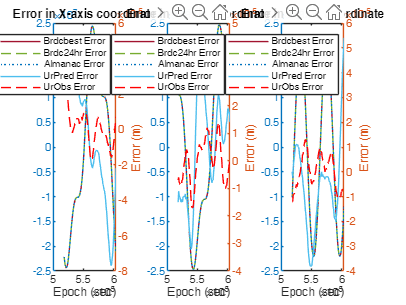

% Read the position using the almanac parameters
almanacdata = readmatrix(almanacFile);

% Read the position using the predicted and observed ephemeris data
urPreddata_0 = readSP3(urPredFile);
urObsdata_0 = readSP3(urObsFile);

% Extract PRN12 data from the predicted and observed data
urPreddata = NaN(96,4);
urObsdata = NaN(96,4);

for j = 1:96
    % Time of transmission
    time_of_transmission = 518400 + (j - 1) * 900;
    
    % Iterate through urPreddata_0 and filter rows
    for i = 1:size(urPreddata_0, 1)
        % Check if the first number is 12 and third number equals time_of_transmission
        if urPreddata_0(i, 1) == 12 && urPreddata_0(i, 3) == time_of_transmission
            % Store columns 3, 4, 5, and 6 in urPreddata
            urPreddata(j, :) = [urPreddata_0(i, 3), urPreddata_0(i, 4), urPreddata_0(i, 5), urPreddata_0(i, 6)];
        end
    end
end

for j = 1:96
    % Time of transmission
    time_of_transmission = 518400 + (j - 1) * 900;

    % Iterate through urPreddata_0 and filter rows
    for i = 1:size(urObsdata_0, 1)
        % Check if the first number is 12 and third number equals time_of_transmission
        if urObsdata_0(i, 1) == 12 && urObsdata_0(i, 3) == time_of_transmission
            % Store columns 3, 4, 5, and 6 in urPreddata
            urObsdata(j, :) = [urObsdata_0(i, 3), urObsdata_0(i, 4), urObsdata_0(i, 5), urObsdata_0(i, 6)];
        end
    end
end

% Error computation
brdcbest_error = brdcbest - precisedata;
brdcbest_error(:, 1) = brdcbest(:, 1);

brdc24hr_error = brdc24hr - precisedata;
brdc24hr_error(:, 1) = brdc24hr(:, 1);

almanac_error = almanacdata - precisedata;
almanac_error(:, 1) = almanacdata(:, 1);

urPred_error = urPreddata - precisedata;
urPred_error(:, 1) = urPreddata(:, 1);

urObs_error = urObsdata - precisedata;
urObs_error(:, 1) = urObsdata(:, 1);

% Plot errors as a function of time
figure;
subplot(1,3,1);
yyaxis left;
plot(brdcbest_error(:, 1), brdcbest_error(:, 2), 'Color', '#A2142F');
hold on;
plot(brdcbest_error(:, 1), brdc24hr_error(:, 2), 'Color', '#77AC30');
plot(brdcbest_error(:, 1), almanac_error(:, 2), 'Color', '#0072BD');

yyaxis right;
plot(brdcbest_error(:, 1), urPred_error(:, 2), 'Color', '#4DBEEE');
plot(brdcbest_error(:, 1), urObs_error(:, 2), 'r');
legend('Brdcbest Error', 'Brdc24hr Error', 'Almanac Error', 'UrPred Error', 'UrObs Error');
xlabel('Epoch (sec)');
ylabel('Error (m)');
title('Error in X-axis coordinate')

subplot(1,3,2);
yyaxis left;
plot(brdcbest_error(:, 1), brdcbest_error(:, 3), 'Color', '#A2142F');
hold on;
plot(brdcbest_error(:, 1), brdc24hr_error(:, 3), 'Color', '#77AC30');
plot(brdcbest_error(:, 1), almanac_error(:, 3), 'Color', '#0072BD');
yyaxis right;
plot(brdcbest_error(:, 1), urPred_error(:, 3), 'Color', '#4DBEEE');
plot(brdcbest_error(:, 1), urObs_error(:, 3), 'r');
legend('Brdcbest Error', 'Brdc24hr Error', 'Almanac Error', 'UrPred Error', 'UrObs Error');
xlabel('Epoch (sec)');
ylabel('Error (m)');
title('Error in Y-axis coordinate')

subplot(1,3,3);
yyaxis left;
plot(brdcbest_error(:, 1), brdcbest_error(:, 4), 'Color', '#A2142F');
hold on;
plot(brdcbest_error(:, 1), brdc24hr_error(:, 4), 'Color', '#77AC30');
plot(brdcbest_error(:, 1), almanac_error(:, 4), 'Color', '#0072BD');
yyaxis right;
plot(brdcbest_error(:, 1), urPred_error(:, 4), 'Color', '#4DBEEE');
plot(brdcbest_error(:, 1), urObs_error(:, 4), 'r');
legend('Brdcbest Error', 'Brdc24hr Error', 'Almanac Error', 'UrPred Error', 'UrObs Error');
xlabel('Epoch (sec)');
ylabel('Error (m)');
title('Error in Z-axis coordinate')

## Task4 - Error Analysis

% For broadcast best data
brdcbest_max_error = max(abs(brdcbest_error(:, 2:4)));
brdcbest_mean_error = mean(brdcbest_error(:, 2:4));
brdcbest_std_error = std(brdcbest_error(:, 2:4));
brdcbest_rmse_error = sqrt(mean(brdcbest_error(:, 2:4).^2));
fprintf('brdcbest max error: X = %f, Y = %f, Z = %f\n', brdcbest_max_error(1), brdcbest_max_error(2), brdcbest_max_error(3));

brdcbest max error: X = 24387295.317040, Y = 24691303.377770, Z = 22061066.324546


fprintf('brdcbest mean error: X = %f, Y = %f, Z = %f\n', brdcbest_mean_error(1), brdcbest_mean_error(2), brdcbest_mean_error(3));

brdcbest mean error: X = -62870.698999, Y = 30769.788157, Z = -296351.110569


fprintf('brdcbest standard deviation error: X = %f, Y = %f, Z = %f\n', brdcbest_std_error(1), brdcbest_std_error(2), brdcbest_std_error(3));

brdcbest standard deviation error: X = 15187326.095376, Y = 15450992.053006, Z = 15557198.581014


fprintf('brdcbest rmse error: X = %f, Y = %f, Z = %f\n', brdcbest_rmse_error(1), brdcbest_rmse_error(2), brdcbest_rmse_error(3));

brdcbest rmse error: X = 15108149.182323, Y = 15370338.268874, Z = 15478796.563302



% For broadcast 24-hour data
brdc24hr_max_error = max(abs(brdc24hr_error(:, 2:4)));
brdc24hr_mean_error = mean(brdc24hr_error(:, 2:4));
brdc24hr_std_error = std(brdc24hr_error(:, 2:4));
brdc24hr_rmse_error = sqrt(mean(brdc24hr_error(:, 2:4).^2));
fprintf('brdc24hr max error: X = %f, Y = %f, Z = %f\n', brdc24hr_max_error(1), brdc24hr_max_error(2), brdc24hr_max_error(3));

brdc24hr max error: X = 24387295.492350, Y = 24691350.560296, Z = 22061014.837407


fprintf('brdc24hr mean error: X = %f, Y = %f, Z = %f\n', brdc24hr_mean_error(1), brdc24hr_mean_error(2), brdc24hr_mean_error(3));

brdc24hr mean error: X = -62949.730260, Y = 30853.978019, Z = -296283.180693


fprintf('brdc24hr standard deviation error: X = %f, Y = %f, Z = %f\n', brdc24hr_std_error(1), brdc24hr_std_error(2), brdc24hr_std_error(3));

brdc24hr standard deviation error: X = 15187313.671534, Y = 15450978.783601, Z = 15557184.032225


fprintf('brdc24hr rmse error: X = %f, Y = %f, Z = %f\n', brdc24hr_rmse_error(1), brdc24hr_rmse_error(2), brdc24hr_rmse_error(3));

brdc24hr rmse error: X = 15108137.152551, Y = 15370325.237557, Z = 15478780.792727



% For almanac data
almanac_max_error = max(abs(almanac_error(:, 2:4)));
almanac_mean_error = mean(almanac_error(:, 2:4));
almanac_std_error = std(almanac_error(:, 2:4));
almanac_rmse_error = sqrt(mean(almanac_error(:, 2:4).^2));
fprintf('almanac max error: X = %f, Y = %f, Z = %f\n', almanac_max_error(1), almanac_max_error(2), almanac_max_error(3));

almanac max error: X = 24386540.721253, Y = 24690441.452038, Z = 22061108.747012


fprintf('almanac mean error: X = %f, Y = %f, Z = %f\n', almanac_mean_error(1), almanac_mean_error(2), almanac_mean_error(3));

almanac mean error: X = -62809.483270, Y = 30736.944520, Z = -296338.166203


fprintf('almanac standard deviation error: X = %f, Y = %f, Z = %f\n', almanac_std_error(1), almanac_std_error(2), almanac_std_error(3));

almanac standard deviation error: X = 15186958.996200, Y = 15450594.684890, Z = 15557063.739304


fprintf('almanac rmse error: X = %f, Y = %f, Z = %f\n', almanac_rmse_error(1), almanac_rmse_error(2), almanac_rmse_error(3));

almanac rmse error: X = 15107783.748666, Y = 15369942.910878, Z = 15478662.202493




% For the Predicted data
urPred_max_error = max(abs(urPred_error(:, 2:4)));
urPred_mean_error = mean(urPred_error(:, 2:4));
urPred_std_error = std(urPred_error(:, 2:4));
urPred_rmse_error = sqrt(mean(urPred_error(:, 2:4).^2));
fprintf('urPred max error: X = %f, Y = %f, Z = %f\n', urPred_max_error(1), urPred_max_error(2), urPred_max_error(3));

urPred max error: X = 0.000077, Y = 0.000044, Z = 0.000054


fprintf('urPred mean error: X = %f, Y = %f, Z = %f\n', urPred_mean_error(1), urPred_mean_error(2), urPred_mean_error(3));

urPred mean error: X = -0.000007, Y = 0.000005, Z = -0.000006


fprintf('urPred standard deviation error: X = %f, Y = %f, Z = %f\n', urPred_std_error(1), urPred_std_error(2), urPred_std_error(3));

urPred standard deviation error: X = 0.000034, Y = 0.000020, Z = 0.000018


fprintf('urPred rmse error: X = %f, Y = %f, Z = %f\n', urPred_rmse_error(1), urPred_rmse_error(2), urPred_rmse_error(3));

urPred rmse error: X = 0.000034, Y = 0.000020, Z = 0.000019



% For the Observed data
urObs_max_error = max(abs(urObs_error(:, 2:4)));
urObs_mean_error = mean(urObs_error(:, 2:4));
urObs_std_error = std(urObs_error(:, 2:4));
urObs_rmse_error = sqrt(mean(urObs_error(:, 2:4).^2));
fprintf('urObs max error: X = %f, Y = %f, Z = %f\n', urObs_max_error(1), urObs_max_error(2), urObs_max_error(3));

urObs max error: X = 0.000043, Y = 0.000017, Z = 0.000013


fprintf('urObs mean error: X = %f, Y = %f, Z = %f\n', urObs_mean_error(1), urObs_mean_error(2), urObs_mean_error(3));

urObs mean error: X = 0.000002, Y = -0.000000, Z = 0.000000


fprintf('urObs standard deviation error: X = %f, Y = %f, Z = %f\n', urObs_std_error(1), urObs_std_error(2), urObs_std_error(3));

urObs standard deviation error: X = 0.000012, Y = 0.000008, Z = 0.000007


fprintf('urObs rmse error: X = %f, Y = %f, Z = %f\n', urObs_rmse_error(1), urObs_rmse_error(2), urObs_rmse_error(3));

urObs rmse error: X = 0.000012, Y = 0.000008, Z = 0.000007
